# Connect and sample data from a Hokuyo URG-40LX Laser 

% There are too many warnings so just ignore them
warning('off', 'all');

% Cant have more than one serial object, clear others
serialObjs = instrfind;   % Read instrument objs from memory
if ~isempty(serialObjs)   % If there are old objects close them
    fclose(serialObjs);
    delete(serialObjs);
end

% Clear workspace
clear
clc

% Add path
addpath('..')

**Specify which serial port (USB) you have the test bench Hokuyo Lidar plugged into**

comPort = "COM4"; % change based on com port
disp("Com port set")

Com port set


**Connect to Hokuyo Lidar and set its serial communication parameters**

disp("connecting to lidar and setting lidar parameters");

connecting to lidar and setting lidar parameters


disp("expect a short delay while setting............................");

expect a short delay while setting............................


lidar = serial(comPort, "baudrate", 115200);
set(lidar, "Timeout", 2);
set(lidar, "InputBufferSize", 20000);
set(lidar, "Terminator", "LF/CR");

% write a set of Hokuyo parameters to Lidar to configure it
fopen(lidar);
pause(0.3);
fprintf(lidar, "SCIP2.0");
pause(0.3);
fscanf(lidar);
fprintf(lidar, "VV");
pause(0.3);
fscanf(lidar);
fprintf(lidar, "BM");
pause(0.3);
fscanf(lidar);
fprintf(lidar, "MD0044072500");
pause(0.3);
fscanf(lidar);
clc
disp("Lidar Set")

Lidar Set


**Initialize the LIDAR display figure window**

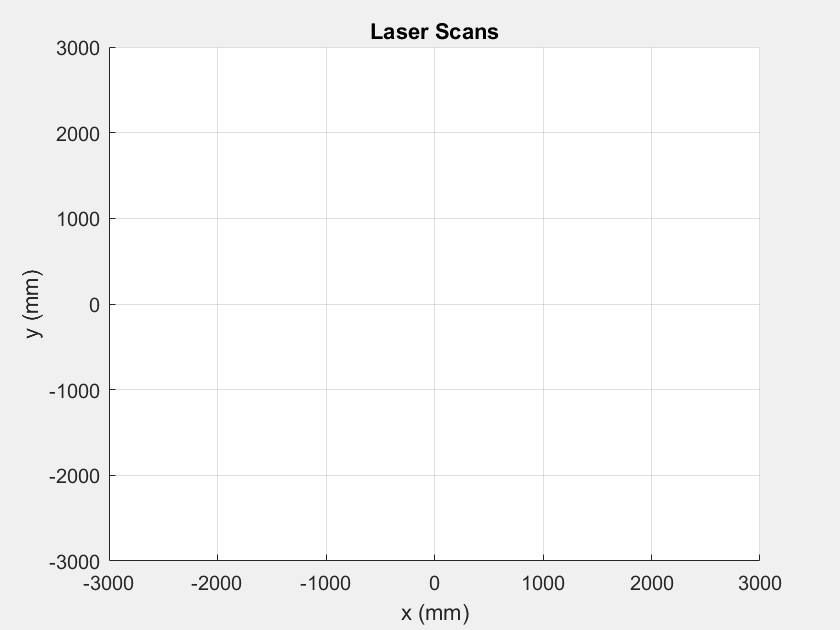

% Setup figure
LaserPlot1.figure = figure('Name', 'Hokuyo URG-40LX data', 'NumberTitle', 'off', 'MenuBar', 'figure', 'units', 'normalized', 'Visible', 'on');
LaserPlot1.axis1 = axes('parent', LaserPlot1.figure, 'units', 'normalized', 'NextPlot', 'replace');
grid(LaserPlot1.axis1, 'on');
LaserPlot1.axis1.Title.String = 'Laser Scans';
LaserPlot1.axis1.XLabel.String = 'X Axis';
LaserPlot1.axis1.YLabel.String = 'Y Axis';

% Create line object to plot data
laserRange = line('Parent', LaserPlot1.axis1, 'XData', [], 'YData', [], 'LineStyle', 'none', 'marker', '.', 'color', 'b', 'LineWidth', 2);
grid on
axis([-3000 3000 -3000 3000]);
xlabel('x (mm)');
ylabel('y (mm)');


disp('Laser scans figure set')

Laser scans figure set



% Create polar figure
polarPlot = figure("Name", "Polar Plot", "NumberTitle","off", "Visible","on");

**Sample and Visualize Data**

Do NOT let this stop - have it continue to next section for shutdown

disp('Read and Plot LIDAR data \, type and hold ctrl-c to stop.');

Read and Plot LIDAR data \, type and hold ctrl-c to stop.


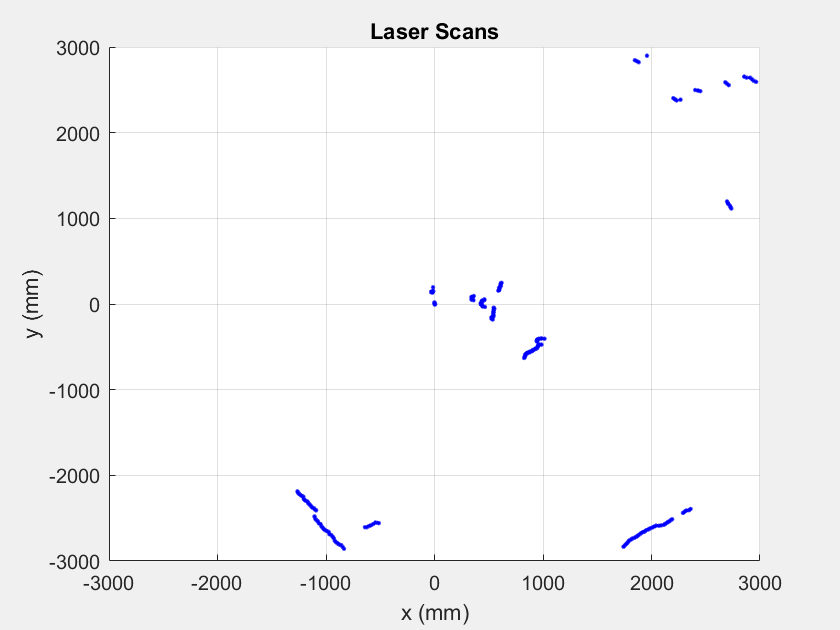

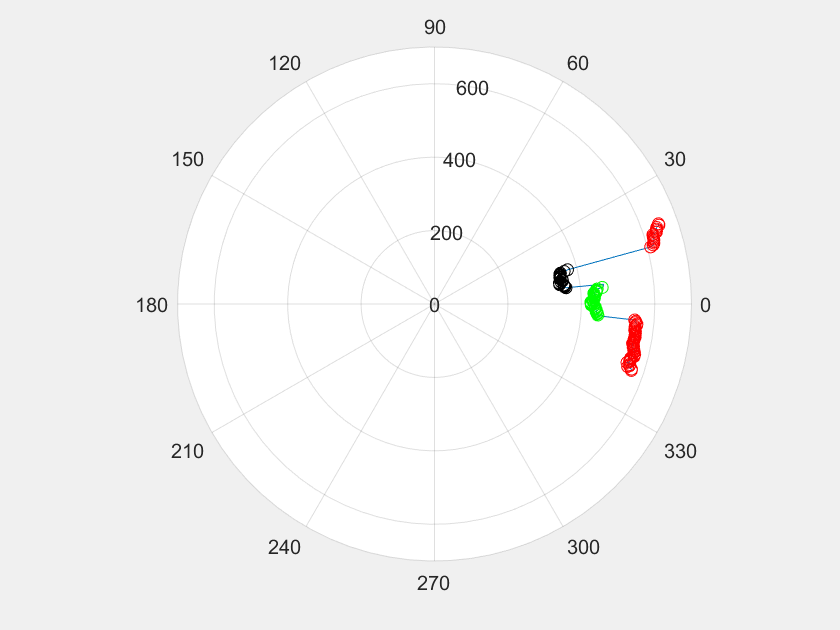


angles = (-120:240/682:120-240/682) * pi / 180;     % Convert sensor steps to angles for plotting
tStart = tic;
wiccan = 1;
while (wiccan == 1)  % Continuous loop, ctrl-C to break (or wiccan 1 minute)
    % Convert polar to cartesian
    [A] = FunRoboLidarScan(lidar);
    figure(LaserPlot1.figure);
    laserRange.XData = A .* cos(angles);
    laserRange.YData = A .* sin(angles);
    drawnow;    % Update figures

    % Narrow scope to just hte board
    allowedIndexes = angles < pi/9 & angles > -pi/9 & A > 200;
    boardAngles = angles(allowedIndexes);
    boardRadii = A(allowedIndexes);
    figure(polarPlot);
    polarplot(boardAngles, boardRadii);

    % Holes!
    % Anything further than the closest point of the board is a hole
    holeRadii = boardRadii(boardRadii > 540);
    holeAngles = boardAngles(boardRadii > 540);
    hold on;
    polarplot(holeAngles, holeRadii, "ro");

    % Not holes! (also known as, objects)
    notHoleRadii = boardRadii(boardRadii < 540);
    notHoleAngles = boardAngles(boardRadii < 540);
    objectIndexes1 = abs(notHoleRadii - notHoleRadii(floor(end/4))) < 35;
    objectRadii1 = notHoleRadii(objectIndexes1)';
    objectAngles1 = notHoleAngles(objectIndexes1)';
    polarplot(objectAngles1(:, 1), objectRadii1(:, 1), "go");
    if length(objectRadii1) < length(notHoleRadii)
        objectIndexes2 = abs(notHoleRadii - notHoleRadii(floor(end/4)*3)) < 35;
        objectRadii2 = notHoleRadii(objectIndexes2)';
        objectAngles2 = notHoleAngles(objectIndexes2)';
        polarplot(objectAngles2, objectRadii2, "ko");
    end

    hold off;

    % Pause for next loop
    pause(0.2);
    tElapsed = toc(tStart);
    if (tElapsed > 60)
        wiccan = 0;
    end
end

**Shutdown code**

**PLEASE RUN**

% Shutdown
fprintf(lidar, 'QT');
fclose(lidar);
clear lidar
warning('on');
disp('program ended (?)');

program ended (?)
